# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL 

# SECOND PARTIAL EXAMINATION -  A.Y. 2023/2024

**June 3, 2024**

# Design of a Controller 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure

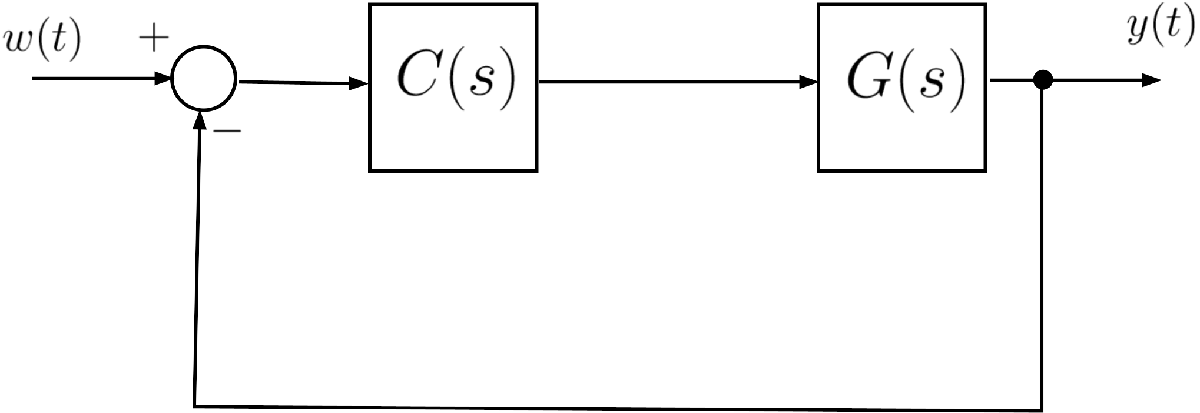	

where $G(s)$ is given by                


$$G(s) = \frac{8.25}{s\,(1+0.125\,s)\,(1+10\,s)}\;$$


## **Question**		

**Q1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- $\left| e(\infty)\right| \le 0.25$ for $w(t) = t\cdot \mathbf{1}(t)$, where $\mathbf{1}(t)$ denotes the unit step function;

- $t_{s\,1\%} \le 7 \,\text{s}$  , where $t_{s\,1\%}$ is the settling time at $1\,\%$ ; 

- $\Delta \% \le 33\%$, where $\Delta \%$ is the maximum percentage overshoot, defined by 

                                        
$$\Delta \% = 100\cdot\frac{y_p-y(\infty)}{y(\infty)}$$
 

            where $y_p$ is the peak-value of the output.

**Hint**: the maximum percentage overshoot $\Delta \%$ depends on the damping factor $\xi$ of the closed-loop dominant poles (refer to Part 7 of the course material) and there is also an approximate relationship between the phase margin $\varphi_m$ and the damping factor of the closed-loop dominant poles (refer to Part 9 of the course material).

## A1: Answer to Question Q1

### Preliminary Analysis of the Requirements

**Req. (Q1.1): **According to the requirement, the open-loop system $L(s) = C(s) \cdot G(s)$ has to be a "type $g=1$  " system [i.e., null steady-state error $e(\infty)$ when the reference input $w(t)$ is a unit step signal ( $w(t) = \mathbf{1}(t)$ ) and the magnituude of the steady-state error must be bounded when the reference input is an unit-slope ramp $w(t) = t\cdot \mathbf{1}(t)$ ]. 

Thus, as preliminary controller, let's apply a simple proportional controller $C_1(s) = \mu_1 >0$ and evaluate the steady-state error when the reference input is $w(t) = t\cdot \mathbf{1}(t)$ (i.e., a ramp signal with a unitary slope)


$$\text{Hyp. : closed-loop system as. stable} \; \Longrightarrow \; e\left(\infty\right) = \lim_{s \to 0} s \, \left[S(s) \cdot \frac{1}{s^2} \right]\;, \frac{1}{s^2} = \mathcal{L} \left(t\cdot \mathbf{1}(t) \right)\;,\quad S(s) =\frac{1}{1+L(s)}\;,\quad L(s) = C_1(s)\cdot G(s)$$


Thus


$$L(s) = \frac{8.25\,\mu_1}{s\,(1+0.125\,s)\,(1+10\,s)} \; \Longrightarrow \; 
e(\infty) = \lim_{s \to 0} s \cdot \frac{s\,(1+0.125\,s)\,(1+10\,s)}{s\,(1+0.125\,s)\,(1+10\,s)+8.25\,\mu_1} \cdot \frac{1}{s^2} = \frac{1}{8.25\,\mu_1}$$


Finally


$$\left| e(\infty)\right| \le 0.5 \quad \Longrightarrow \quad \left\vert \frac{1}{8.25 \, \mu_1} \right\vert \le \frac{1}{2} \quad \Longrightarrow \quad 
\mu_1 \ge \frac{200}{825} \approx 0.24$$


**Req. (Q1.2)**: According to (Part 9 - Slide 44) of the course material


$$\left\{\begin{array}{lcl}
\varphi_m > 75^{\circ} & \Longrightarrow & t_{s\,1\%} \approx \frac{4.6}{\omega_c} \\
 \varphi_m < 75^{\circ} & \Longrightarrow &  t_{s\,1\%} \approx \frac{4.6}{\xi \omega_c} \,,\; \xi \approx \frac{\varphi_m}{100}
\end{array} \right.$$


Thus


$$t_{s\,1\%} \le 7 \,\text{s} \quad \Longrightarrow \quad
\left\{\begin{array}{lcl}
\varphi_m > 75^{\circ} & \Longrightarrow & \frac{4.6}{\omega_c} \le 7 
\quad \Longrightarrow  \quad \omega_c \ge \frac{4.6}{7} \approx 0.657 \\
 \varphi_m < 75^{\circ} & \Longrightarrow &  \frac{\varphi_m}{100} \omega_c \ge  \frac{4.6}{7} \approx 0.657 \quad \Longrightarrow \quad \varphi_m \cdot \omega_c \ge 65.7
\end{array} \right.$$


**Req. (Q1.3)**: According to (Part 7 - slide 27) of the course material


$$\Delta \% = 100 \cdot e^{-\,\frac{\xi \, \pi}{\sqrt{1-\xi^2}}} \quad \Longrightarrow \quad 100 \cdot e^{-\,\frac{\xi \, \pi}{\sqrt{1-\xi^2}}} \le 33 \quad \Longrightarrow \quad e^{-\,\frac{\xi \, \pi}{\sqrt{1-\xi^2}}} \le 0.33 $$


After some manipulations, you obtain


$$ \frac{\xi \, \pi}{\sqrt{1-\xi^2}} \ge \ln \frac{100}{33} \quad \Longrightarrow \quad \xi \ge \frac{\ln \frac{100}{33}}{\sqrt{\pi^2+\left(\ln \frac{100}{33}\right)^2}} \approx 0.333$$


Now, according to (Part 9 - Slide 43) of the course material, it holds $\xi \approx \frac{\varphi_m}{100}$

Thus;


$$\xi \ge 0.333 \quad \Longrightarrow \quad \varphi_m > 34^{\circ}$$


**Summing Up**: 

- **Req. (Q1.1)**: $\mu_1 \ge \bar{\mu_1} = 0.24$, where $C(s) = \mu_1\,$

- **Req. (Q1.2)**: $\left\{\begin{array}{lcl}
\varphi_m > 75^{\circ} & \Longrightarrow & \omega_c \ge  0.657\\
 \varphi_m < 75^{\circ} & \Longrightarrow & \varphi_m \cdot \omega_c \ge 65.7
\end{array} \right.$

- **Req. (Q1.3)**: $\varphi_m > 34^{\circ}$

### Solution 1

#### Design Strategy

- Check if it is possible to meet all the requirements, by selecting a crossover frequency corresponding to a phase margin $\varphi_m > 75^{\circ$

- If not, then check if feasible to obtain $\varphi_m \approx 40^{\circ$ or (better choice) $\varphi_m \approx 50^{\circ$, by canceling the "slow" pole, while meeting the other two requirements.

#### Design Procedure

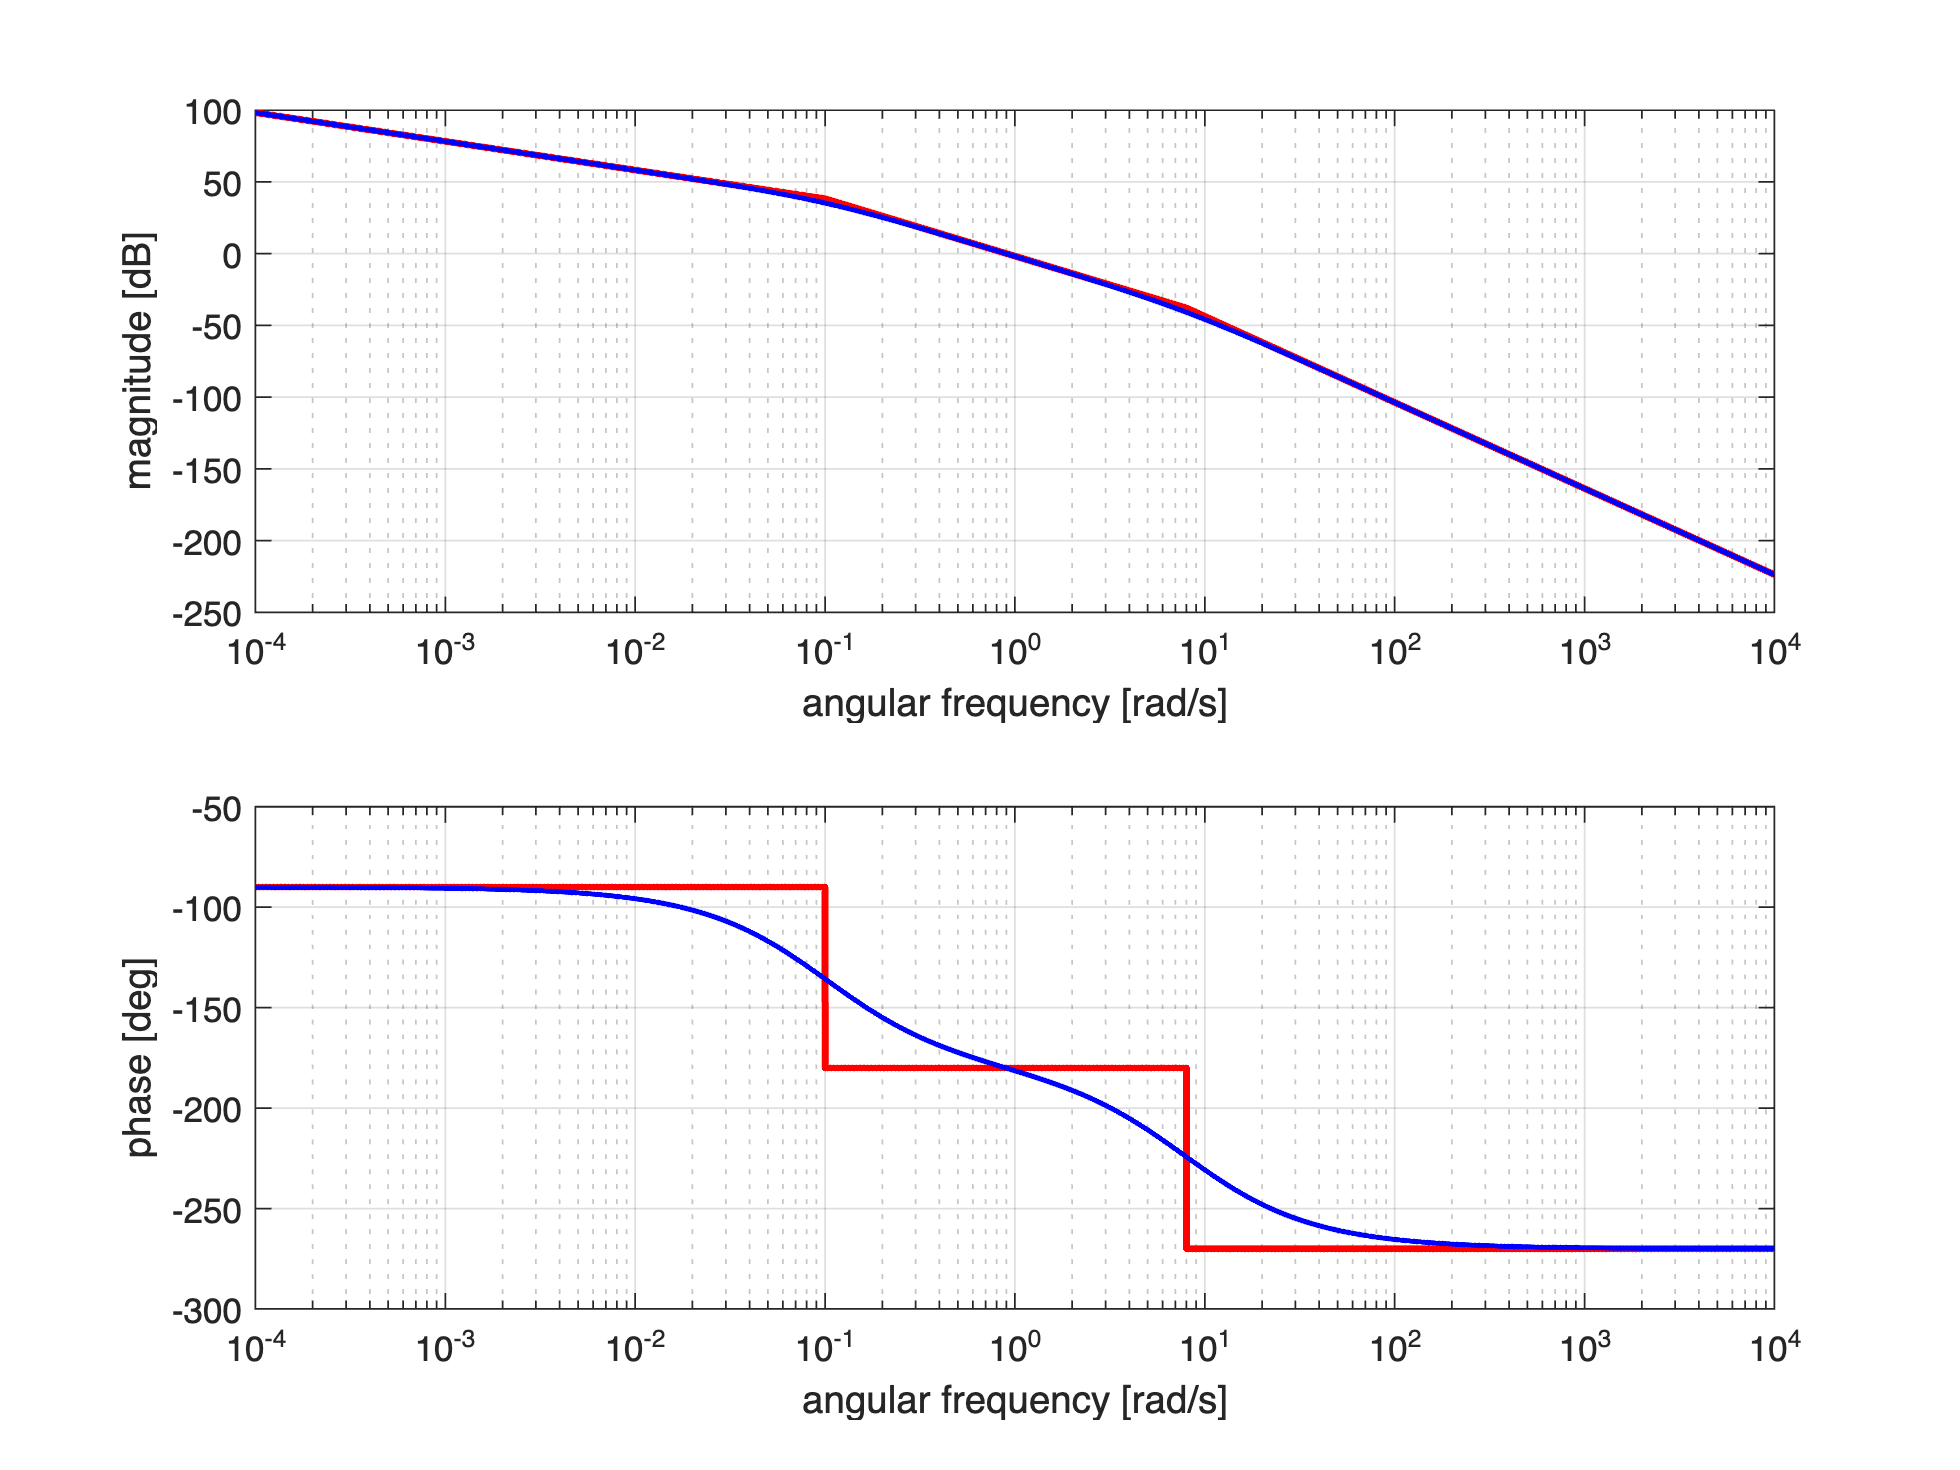

clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gs = 8.25/(s*(1+s/8)*(1+10*s)); % the process G(s)

C_1s = 1; % a simple P controller that meets Req. (Q1.1)
Ls = C_1s*Gs;

figure;
drawBodediagrams(Ls)

**Remark: **as you can notice, the phase margin assumes values such that $\varphi_m > 75^{\circ}$if and only if $\omega_c \le 0.01$ rad/s. We are definitively unable to meet all the requirements. 

**Loop Shaping: "Canceling" the Slow Pole**

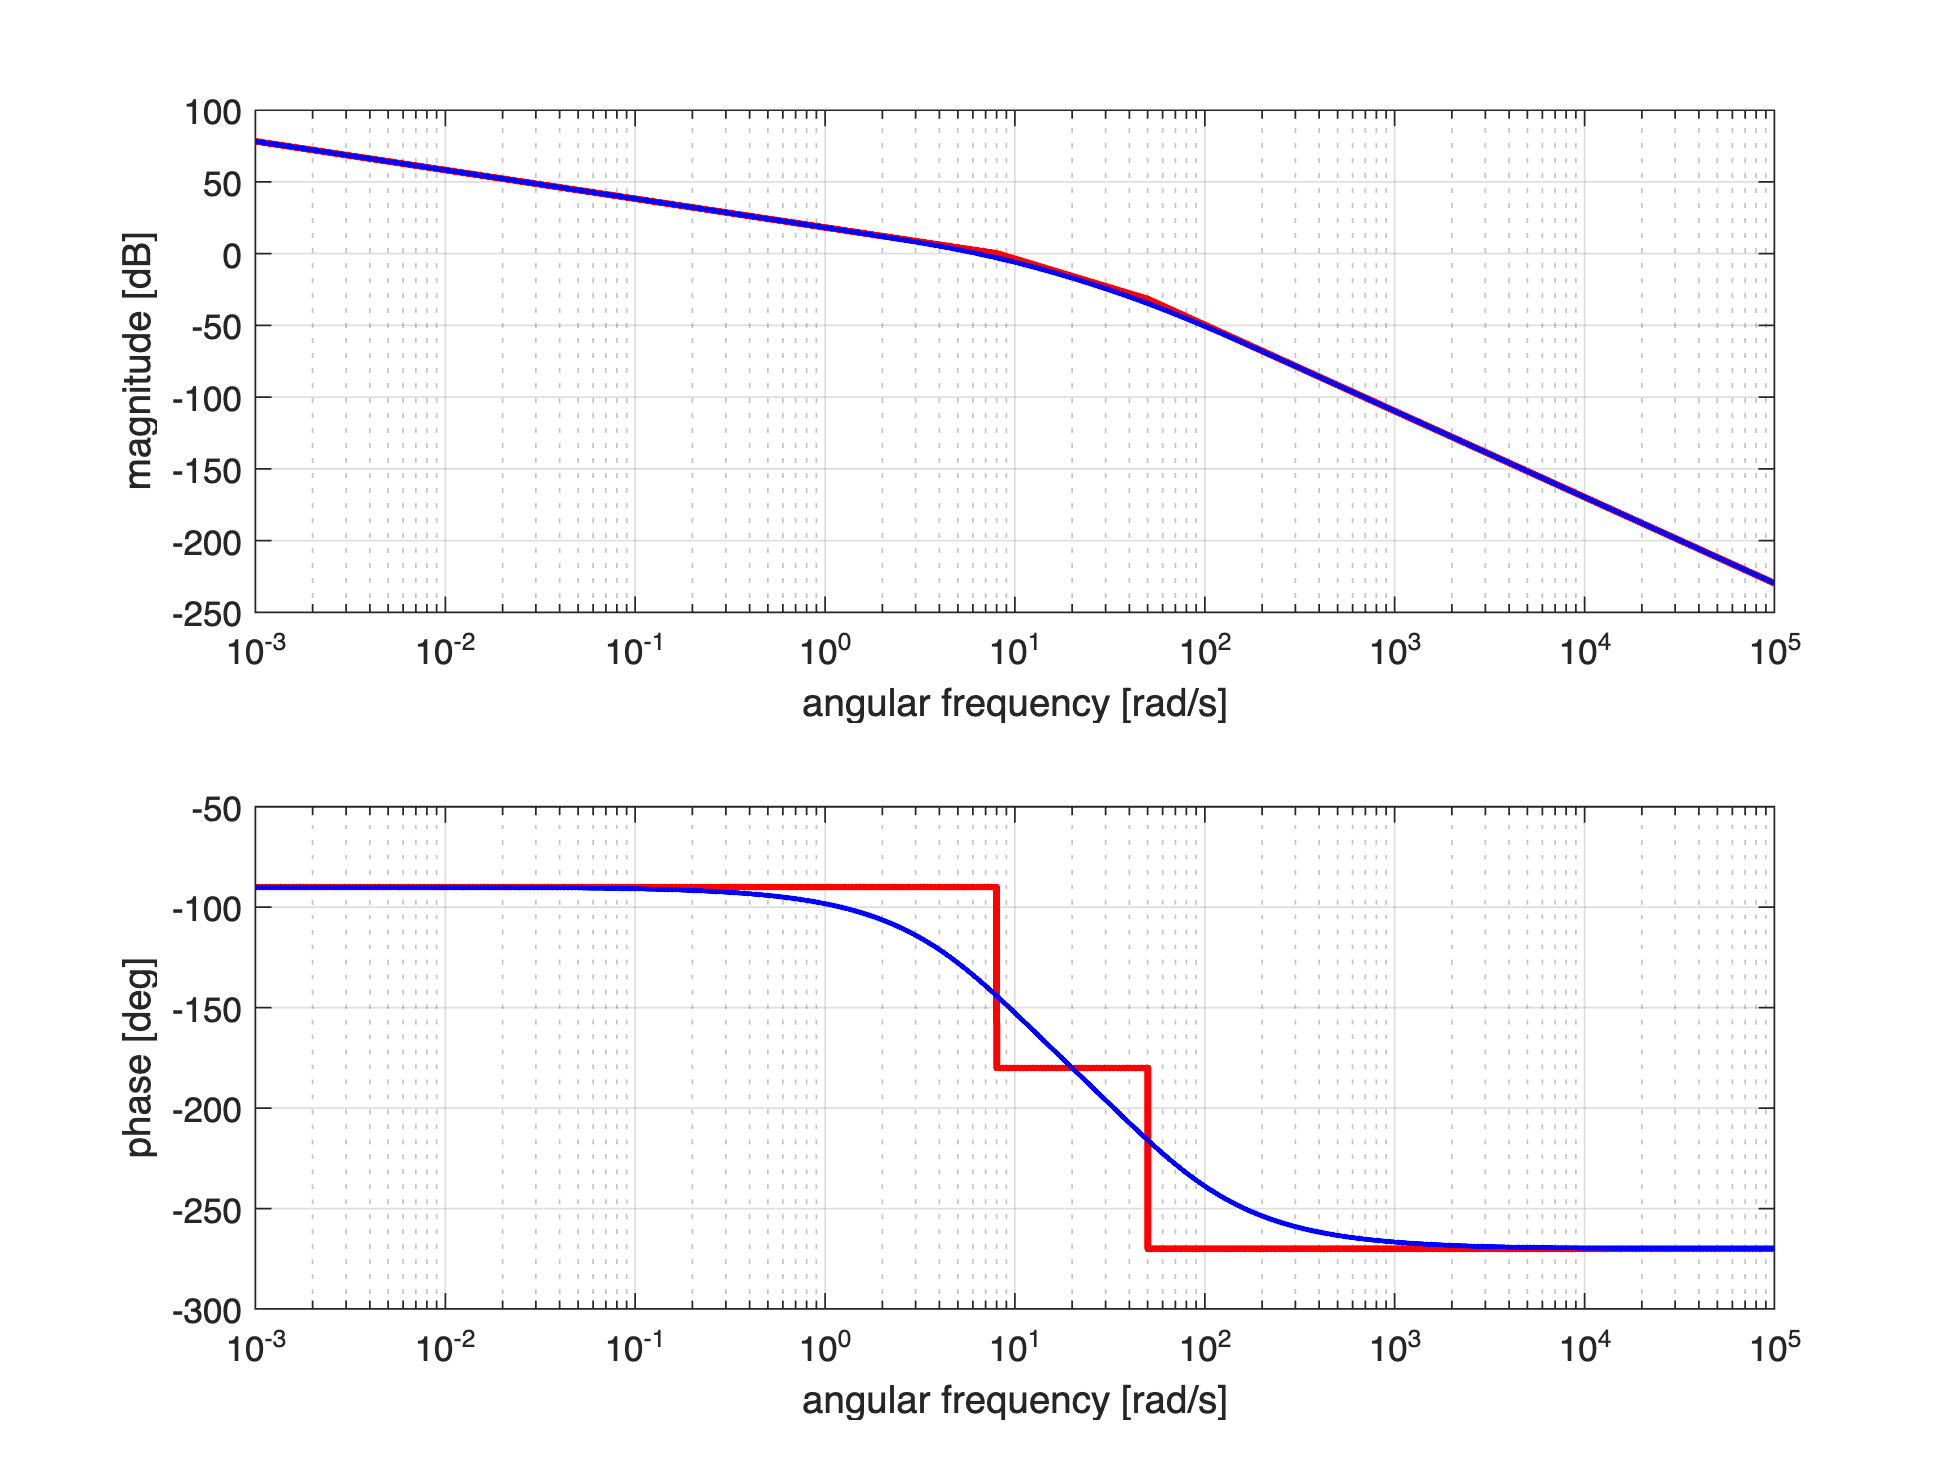


C2_s = (1+10*s)/(1+s/50); % let's cancel the "slow" pole 
                          % and add a "fast" one 
Cs = C_1s * C2_s;

Ls_trial1 = minreal(Cs*Gs);

figure;
drawBodediagrams(Ls_trial1)


rmpath(genpath('BodeDiagram/'))

A **visual inspection** of the phase diagram shows that at the angular frequency $\bar \omega = 3\;\text{rad/s}$ the phase of the frequency response is definitely greater than $-115^{\circ}$, so that requirement Q1.3 is certainly fulfilled. 

bar_omega = 3; % rad/s -- What if it was the crossover frequency?


Let's compute what could be the phase margin if $\omega_c = \bar \omega$:


argLbarOM = rad2deg(angle(freqresp(Ls_trial1, bar_omega)))

argLbarOM = -113.9897

((argLbarOM+180)>34)&((argLbarOM+180)<75) % Req. (Q1.3)

ans = logical
   1


Requirement Q1.3 would be fulfilled. What about requirement Q1.2?

(((argLbarOM+180)*bar_omega) > 65.7)

ans = logical
   1


Req. (Q1.2) would also be fulfilled.

What about Req. (Q1.1)? Let's compute the gain $\mu_1$ in order to impose $\omega_c =\bar \omega$


$$\mu_1: \left\vert L\left(j\bar \omega\right)\right\vert = 1\;\Longrightarrow\; 
\left\vert \frac{8.25\,\mu_1}{j\bar{\omega}\,\left(1+j\frac{\bar \omega}{8}\right)\,\left(1+j \frac{\bar \omega}{50}\right)} \right\vert = 1 \;\Longrightarrow\;
\frac{8.25\,\mu_1}{3\,\sqrt{1+\frac{9}{64}}\,\sqrt{1+\frac{9}{2500}}} =1$$


Thus


$$\mu_1 = \frac{3\,\sqrt{\frac{73}{64}}\, \sqrt{\frac{2509}{2500}}}{8.25} = 
\frac{3\,\sqrt{183157}}{400\cdot 8.25} \approx 0.389\quad \Longrightarrow \quad \mu_1 > \bar\mu_1 = 0.24$$


Requirement Q1.1 would be fulfilled.

Using MATLAB:


muC = 1/abs(freqresp(Ls_trial1, bar_omega))

muC = 0.3891

**Summing Up**:

Using the controller


$$C(s) = 0.389 \cdot \frac{1+10\,s}{1+\frac{s}{50}$$


all the requirements are met.

#### Fine Tuning 

Let's import the controller in the Control System Designer app for a fine tuning.

Cs = 0.389*(1+10*s)/(1+s/50);

Ls = minreal(Cs*Gs)


Ls =
 
          1284
  --------------------
  s^3 + 58 s^2 + 400 s
 
Continuous-time transfer function.
Model Properties



controlSystemDesigner(Gs, Cs)

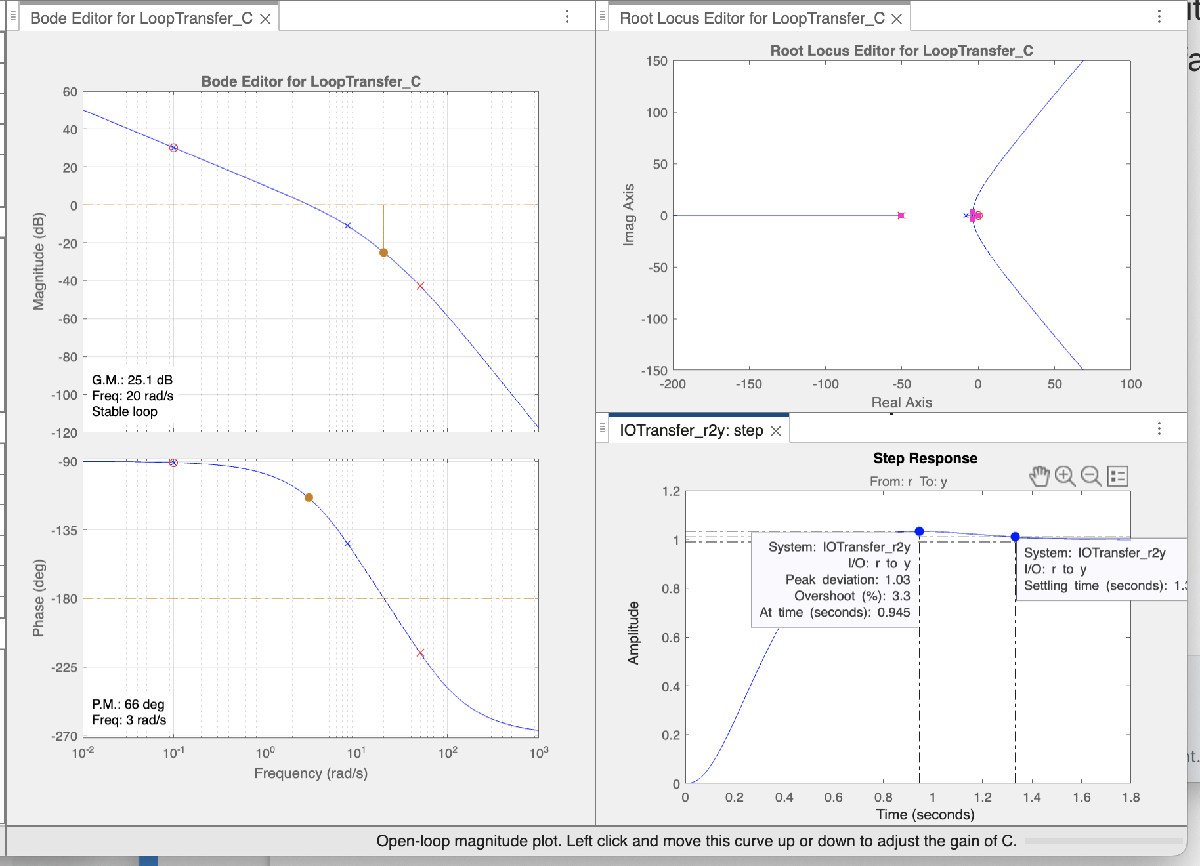

No needs to more fine tuning: all the requirements are met. The session `MAT-file` corresponding to this Figure is `CSD_Solution1.mat .`

### Solution 2

#### Design Strategy

- Cancel both the poles in $p_2=-0.1$ and $p_3=-8$ and insert two other "very fast" poles, with the aim to enlarge the interval of angular frequencies corresponding to the phase margin $\hat \varphi_m \approx +90^{\circ}$

#### Design Procedure

Let's select the static controller $C_1(s) = \mu_1$, with $\mu_1>\bar \mu_1$ in order to fulfill the req. (Q1.1). Moreover, select as dynamic controller $C_2(s)$ the following


$$C_2(s) = \frac{\left(1+10\,s\right)\,\left(1+\frac{s}{8}\right)}{\left(1+\frac{s}{150}\right)\,\left(1+\frac{s}{175}\right)}$$


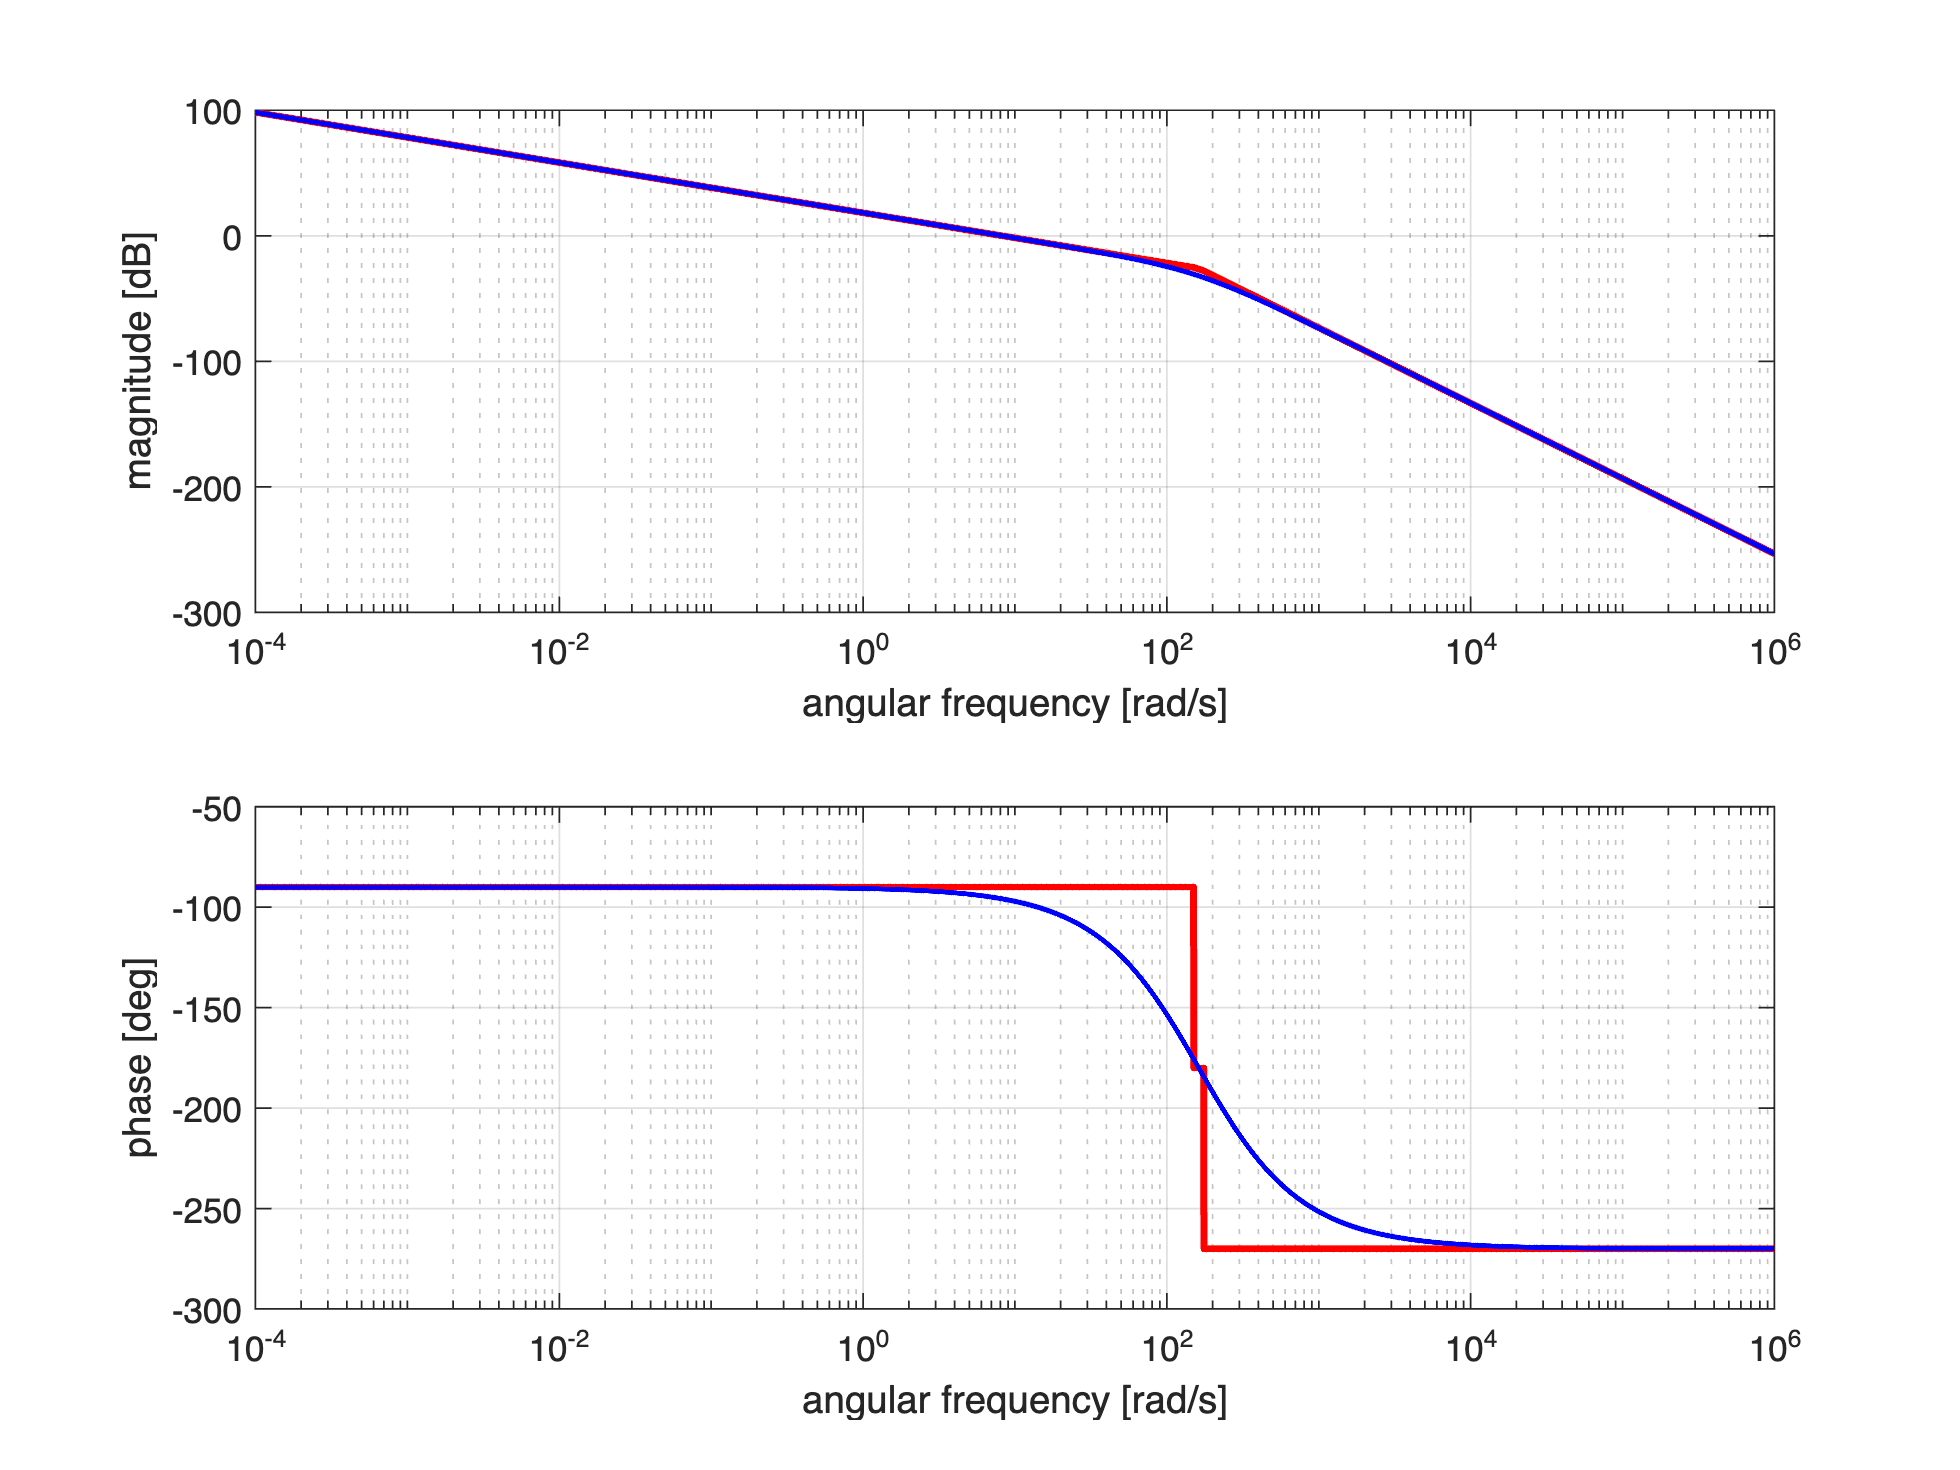

clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gs = 8.25/(s*(1+s/8)*(1+10*s)); % the process G(s)

C_1s = 1; % a simple P controller that meets Req. (Q1.1)
C_2s = (1+10*s)*(1+s/8)/((1+s/150)*(1+s/175));
Cs = C_1s*C_2s;

Ls = minreal(Cs*Gs);
om_vals = logspace(-4,+6,1e4);
figure;
drawBodediagrams(Ls, om_vals)

rmpath(genpath('BodeDiagram/'))


A **visual inspection** of the phase diagram shows that at the angular frequency $\bar \omega = 10\;\text{rad/s}$ the phase of the frequency response is approximatively  $-90^{\circ}$, so that **both requirements (Q1.2) and (Q1.3) are certainly fulfilled**. 

bar_omega = 10; % rad/s -- What if it was the crossover frequency?


Let's compute what could be the phase margin if $\omega_c = \bar \omega$:


argLbarOM = rad2deg(angle(freqresp(Ls, bar_omega)))

argLbarOM = -97.0846

((argLbarOM+180)>75) & (bar_omega > 0.657) % Reqs (Q1.3) & (Q1.2) both are met.

ans = logical
   1


What about Req. (Q1.1)? Let's compute the gain $\mu_1$ in order to impose $\omega_c =\bar \omega$


$$\mu_1: \left\vert L\left(j\bar \omega\right)\right\vert = 1\;\Longrightarrow\; 
\left\vert \frac{8.25\,\mu_1}{j\bar{\omega}\,\left(1+j\frac{\bar \omega}{150}\right)\,\left(1+j \frac{\bar \omega}{175}\right)} \right\vert = 1 \;\Longrightarrow\;
\frac{8.25\,\mu_1}{10\,\sqrt{\frac{226}{225}}\,\sqrt{\frac{1229}{1225}}} =1$$


Thus


$$\mu_1 = \frac{10\,\sqrt{\frac{226}{225}}\,\sqrt{\frac{1229}{1225}}}{8.25}  \approx 1.217\quad \Longrightarrow \quad \mu_1 > \bar\mu_1=0.24$$


Requirement Q1.1 would be fulfilled.

Using MATLAB:


muC = 1/abs(freqresp(Ls, bar_omega))

muC = 1.2168

**Summing Up**:

Using the controller


$$C(s) = 1.217 \cdot \frac{\left(1+10\,s\right)\,\left(1+\frac{s}{8}\right)}{\left(1+\frac{s}{150}\right)\,\left(1+\frac{s}{175}\right)}$$


all the requirements are met.

#### Fine Tuning 

Let's import the controller in the Control System Designer app for a fine tuning.

Cs = 1.217*(1+10*s)*(1+s/8)/((1+s/150)*(1+s/175));

Ls = minreal(Cs*Gs)


Ls =
 
           2.636e05
  --------------------------
  s^3 + 325 s^2 + 2.625e04 s
 
Continuous-time transfer function.
Model Properties



controlSystemDesigner(Gs, Cs)

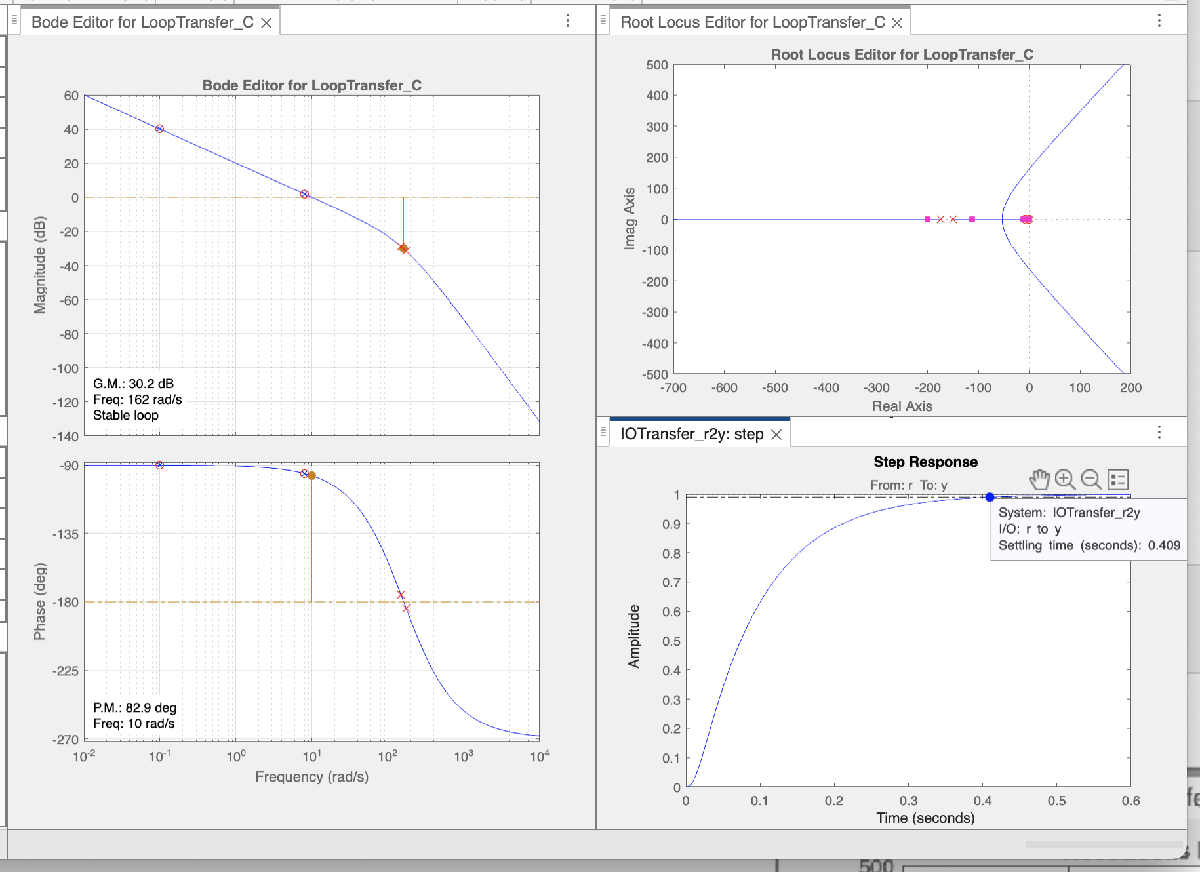

No needs to more fine tuning: all the requirements are met. The session `MAT-file` corresponding to this Figure is `CSD_Solution2.mat .`